% Analytical solution from "balanis_advanced_engineering_electromagnetics" page 614

warning('I''m not sure this is correct!')


tic

close all
clear
clc

syms rho phi x y z real
syms n_x n_y real
syms mu epsilon real positive
syms omega real positive
syms H_0 real
syms R real positive
syms k integer positive

% Numerical values
mu=1;
epsilon=1;
omega=16;
H_0=1;
R=1/2;

% Phase constant
beta=omega*sqrt(mu*epsilon)

beta = 16


% Use auxiliary variables
syms beta_rho real % beta_rho=beta*rho
syms beta_R   real % beta_R  =beta*R

% Fourier summation
N_fourier=1;
H_z=0;
E_rho=0;
E_phi=0;
for k=-N_fourier:+N_fourier
  % Magnetic field
  H_z=H_z...
     +H_0*1i^(-k)*(...
                   besselj(k,beta_rho)...
             -diff(besselj(k,beta_R),beta_R)...
             /diff(besselh(k,2,beta_R),beta_R)...
                  *besselh(k,2,beta_rho)...
                  )*exp(1i*k*phi);

  % Electric field
  E_rho=E_rho...
       +H_0/(1i*omega*epsilon)*1/rho*k*1i^(-k+1)*(...
                                                  besselj(k,beta_rho)...
                                            -diff(besselj(k,beta_R),beta_R)...
                                            /diff(besselh(k,2,beta_R),beta_R)...
                                                 *besselh(k,2,beta_rho)...
                                                 )*exp(1i*k*phi);
  E_phi=E_phi...
       -beta*H_0/(1i*omega*epsilon)*1i^(-k)*(...
                                        diff(besselj(k,beta_rho),beta_rho)...
                                       -diff(besselj(k,beta_R),beta_R)...
                                       /diff(besselh(k,2,beta_R),beta_R)...
                                       *diff(besselh(k,2,beta_rho),beta_rho)...
                                            )*exp(1i*k*phi);
end

% % Simplify expressions
% H_z  =simplify(H_z)
% E_rho=simplify(E_rho)
% E_phi=simplify(E_phi)

% Replace auxiliary variables
H_z  =subs(H_z  ,[beta_rho,beta_R],[beta*rho,beta*R]);
E_rho=subs(E_rho,[beta_rho,beta_R],[beta*rho,beta*R]);
E_phi=subs(E_phi,[beta_rho,beta_R],[beta*rho,beta*R]);

% Reaplce cylindrical coordinates
H_z  =subs(H_z  ,[rho,phi],[sqrt(x^2+y^2),atan2(y,x)]);
E_rho=subs(E_rho,[rho,phi],[sqrt(x^2+y^2),atan2(y,x)]);
E_phi=subs(E_phi,[rho,phi],[sqrt(x^2+y^2),atan2(y,x)]);

% Change of reference system
E_x=cos(atan2(y,x))*E_rho-sin(atan2(y,x))*E_phi;
E_y=sin(atan2(y,x))*E_rho+cos(atan2(y,x))*E_phi;

% % Simplify expressions
% H_z=simplify(H_z)
% E_x=simplify(E_x)
% E_y=simplify(E_y)

% Cartesian coordinates and normal
X=[x,y];
n=[n_x;n_y];

% Rename magnetic and electric field
H=H_z;
E=[E_x;E_y];

% % Incident field
% g=simplify(cross([0;0;H],[n;0])-sqrt(epsilon/mu)*cross([n;0],cross([E;0],[n;0])));
% g=g(1:2)

% Check residual of magnetic field
R_H=simplify(...
    1i*mu*omega*H...
    +mycurl(E,X))

$$R\_H = 0$$


% Check residual of electric field
R_E=simplify(...
    1i*epsilon*omega*E...
    -mycurl(H,X))

$$R\_E = \left[\begin{array}{c} 0\\ 0 \end{array}\right]$$

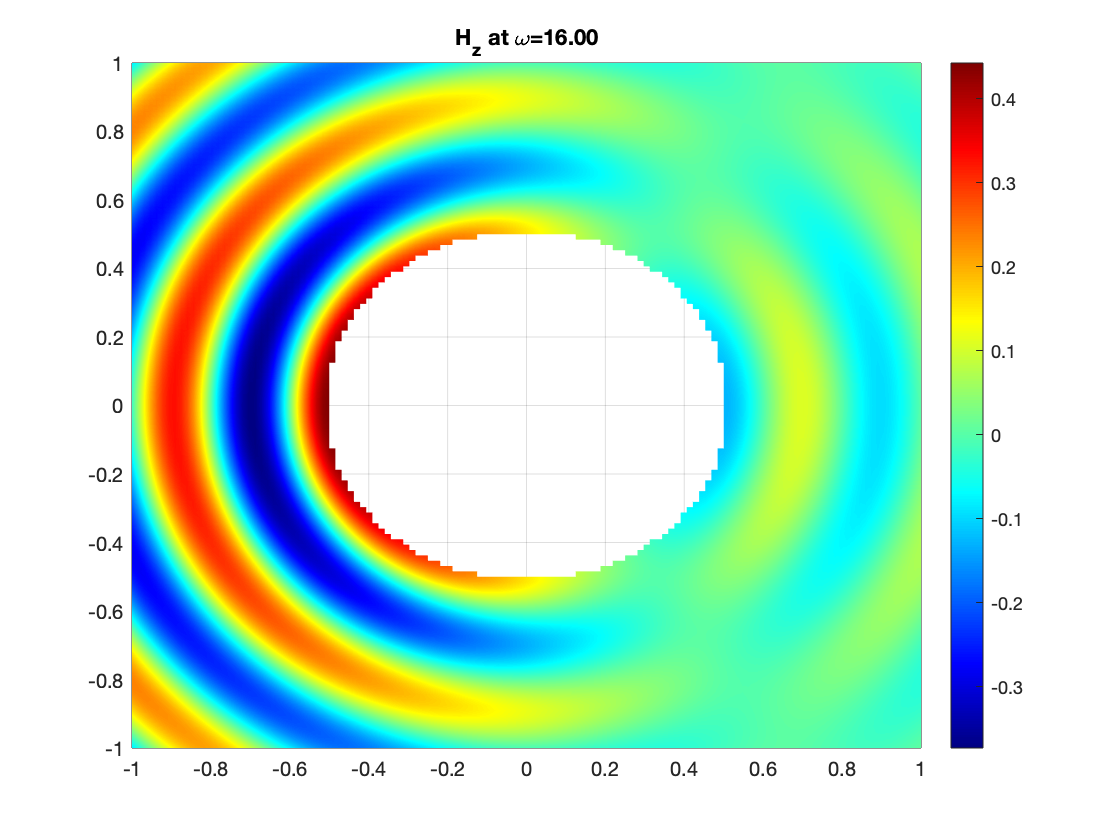


% Plot data
N_plot=2^7;
[x_aux,y_aux]=meshgrid(linspace(-1,+1,N_plot+1));
x=x_aux;
y=y_aux;

% Remove cylinder
x(sqrt(x_aux.^2+y_aux.^2)<R)=NaN;
y(sqrt(x_aux.^2+y_aux.^2)<R)=NaN;

% Plot H_z
H_z_plot=eval(H_z);
figure; surf(x,y,real(H_z_plot));
box on; shading interp; colormap jet; colorbar; view(2);
title(sprintf('H_z at \\omega=%.2f',omega));

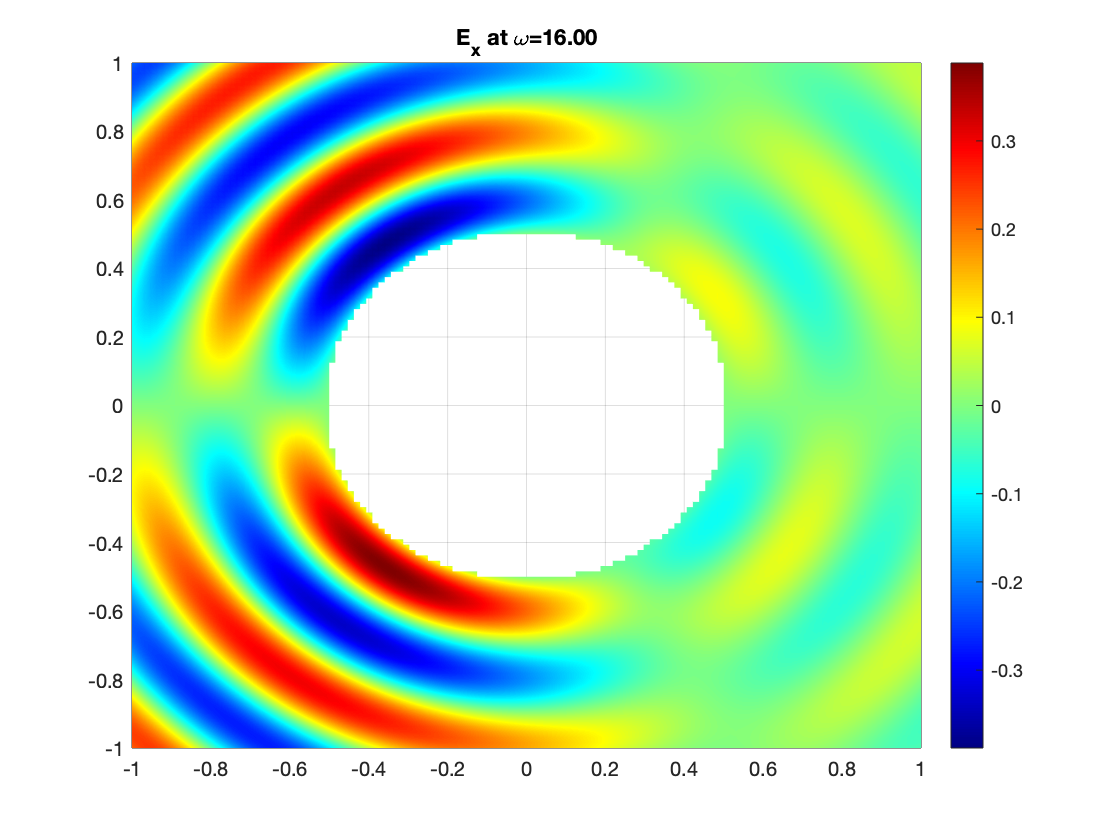

pause(eps)

% Plot E_x
E_x_plot=eval(E_x);
figure; surf(x,y,real(E_x_plot));
box on; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_x at \\omega=%.2f',omega));

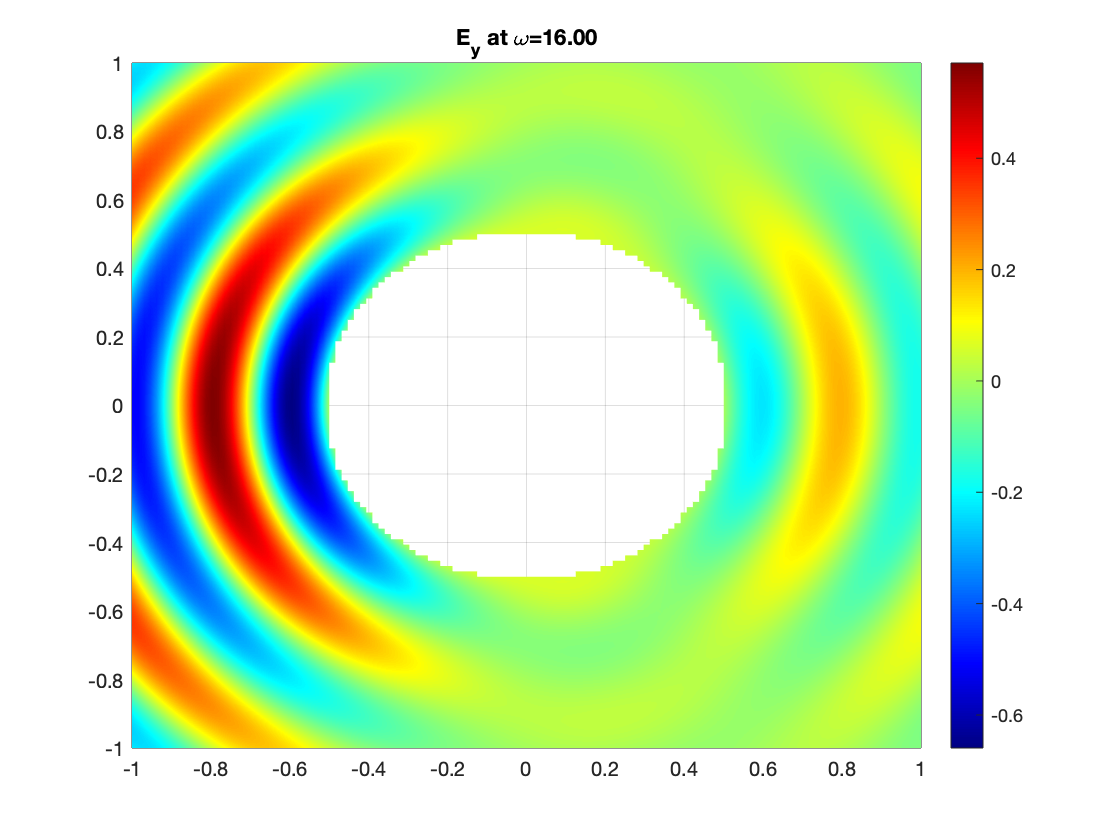

pause(eps)

% Plot E_y
E_y_plot=eval(E_y);
figure; surf(x,y,real(E_y_plot));
box on; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_y at \\omega=%.2f',omega));

pause(eps)

toc

Elapsed time is 2.197224 seconds.
